clear;clc;close all;


## Stage 0 Solar physics

kConstantSolarIrradiance = 1.5;
kLambda = [680;550;440]*1e-3; % wavelength, *1e3 nm
kSolarIrradiance = 0*kLambda + kConstantSolarIrradiance;
kSunAngularRadius = 0.00935/2;
kSolarRadiance = kSolarIrradiance ./ (pi * kSunAngularRadius.^2);
%[kr, kg, kb] = ConvertSpectrumToRadianceFactor(1e3*Lambda(1),1e3*Lambda(2),1e3*Lambda(3));

% Stage 1: Scattering physics
Ns = 6.02e23; % Avogadro's number
N = 2.5e25/Ns; % molecule density / mol
Rscale = 6371000;
H0 = 8500/Rscale; % Atmosphere thickness, m
H1 = 1200/Rscale;
K = N * getCrossSectionTypicalGases([0.26,0.74], kLambda*1e3);
kRayleigh = K*Rscale;
kMieAngstromAlpha = 0.0;
kMieAngstromBeta = 5.328e-3;
kMieSingleScatteringAlbedo = 0.9;
kMiePhaseFunctionG = 0.8;
kMie = 0*kMieAngstromBeta ./ H1 .* ((kLambda*1e3) .^ -kMieAngstromAlpha);

% Stage 2: Space directions
planetCenter = [0,0,0];
rGround = 1; % scaled to 1
rAtmosphere = 6456000/6371000; % scaled to 0.011

bUseCachedScatteringData = false;

% Stage 3: Setup atmosphere datastructure
atmosphere.Rg = rGround;
atmosphere.Rt = rAtmosphere;
atmosphere.sun_angular_radius = kSunAngularRadius;
atmosphere.rayleigh_density = @(h)exp(-(h)/H0);
atmosphere.rayleigh = kRayleigh;
atmosphere.rayleigh_scattering = kRayleigh ./ kLambda.^4;
atmosphere.mie_density = @(h)exp(-(h)/H1);
atmosphere.mie_scattering = kMie * kMieSingleScatteringAlbedo;
atmosphere.mie_extinction = kMie;
atmosphere.mie_phase_function_g = kMiePhaseFunctionG;
atmosphere.mu_s_min = -sqrt(1-(rGround/rAtmosphere)^2);


## Stage 3.1: Precompute optical depth

if bUseCachedScatteringData
    u_rDist = linspace(0,1,64);
    u_muDist = linspace(0,1,256);
    [U_R0,U_MU0] = ndgrid(u_rDist, u_muDist);

    u_rDist = linspace(0,1,32);
    u_muDist = [linspace(0,0.5-1e-6,64),linspace(0.5+1e-6,1,64)];
    u_musDist = linspace(0,1,32);
    u_nuDist = linspace(0,1,8);
    [U_R,U_MU,U_MUS,U_NU] = ndgrid(u_rDist,u_muDist,u_musDist,u_nuDist);

    load("Earth.mat")
end

if ~bUseCachedScatteringData
    u_rDist = linspace(0,1,64);
    u_muDist = linspace(0,1,256);
    [U_R0,U_MU0] = ndgrid(u_rDist, u_muDist);
    [R,MU] = RMuDecoding(atmosphere, U_R0,U_MU0);

    for i = 1:size(R,1)
        for j = 1:size(R,2)
            Transmittence = ComputeTransmittanceToTopAtmosphereBoundary(atmosphere, R(i,j), MU(i,j));
            for l = 1:numel(kLambda)
               Tex_Transmittence(i,j,l) = Transmittence(l);
            end
        end
    end

end

Tex_Transmittence = single(Tex_Transmittence);
U_R0 = single(U_R0);
U_MU0 = single(U_MU0);

atmosphere.cachedTransmittence = @(u_r, u_mu)(interpn(U_R0,U_MU0,Tex_Transmittence,u_r,u_mu,'linear',0));

## 3.2 Precompute transmittence

if ~bUseCachedScatteringData
u_rDist = linspace(0,1,32);
u_muDist = [linspace(0+1e-6,0.5-1e-6,64),linspace(0.5+1e-6,1-1e-6,64)];
u_musDist = linspace(0,1,32);
u_nuDist = linspace(0,1,8);
[U_R,U_MU,U_MUS,U_NU] = ndgrid(u_rDist,u_muDist,u_musDist,u_nuDist);
[R,MU,MUS,NU, HIT_GROUND] = RMuMusNuDecoding(atmosphere, U_R, U_MU, U_MUS, U_NU);

% transmittence
[rayleigh, mie] = ComputeSingleScattering(atmosphere, ...
    R(:), MU(:), MUS(:), NU(:));
for l = 1:numel(kLambda)
    Tex_Rayleigh(:,:,:,:,l) = reshape(rayleigh(:,l), size(R));
    Tex_Mie(:,:,:,:,l) = reshape(mie(:,l), size(R));
end

%Tex_Rayleigh(:,end,:,:,:) = Tex_Rayleigh(:,end-1,:,:,:);
Tex_Rayleigh = single(Tex_Rayleigh);
Tex_Mie = single(Tex_Mie);
U_R = single(U_R);
U_MU = single(U_MU);
U_MUS = single(U_MUS);
U_NU = single(U_NU);

save("CachedScatteringData.mat","U_R0", "U_MU0", "Tex_Transmittence", ...
    "U_R","U_MU","U_MUS","U_NU","Tex_Rayleigh", "Tex_Mie");
end

atmosphere.cachedRayleigh = @(u_r, u_mu, u_mus, u_nu)(interpn(U_R,U_MU,U_MUS,U_NU,Tex_Rayleigh,u_r,u_mu,u_mus,u_nu,'linear',0));
atmosphere.cachedMie = @(u_r, u_mu, u_mus, u_nu)(interpn(U_R,U_MU,U_MUS,U_NU,Tex_Mie,u_r,u_mu,u_mus,u_nu,'linear',0));

## Stage 4: Aerial perspective

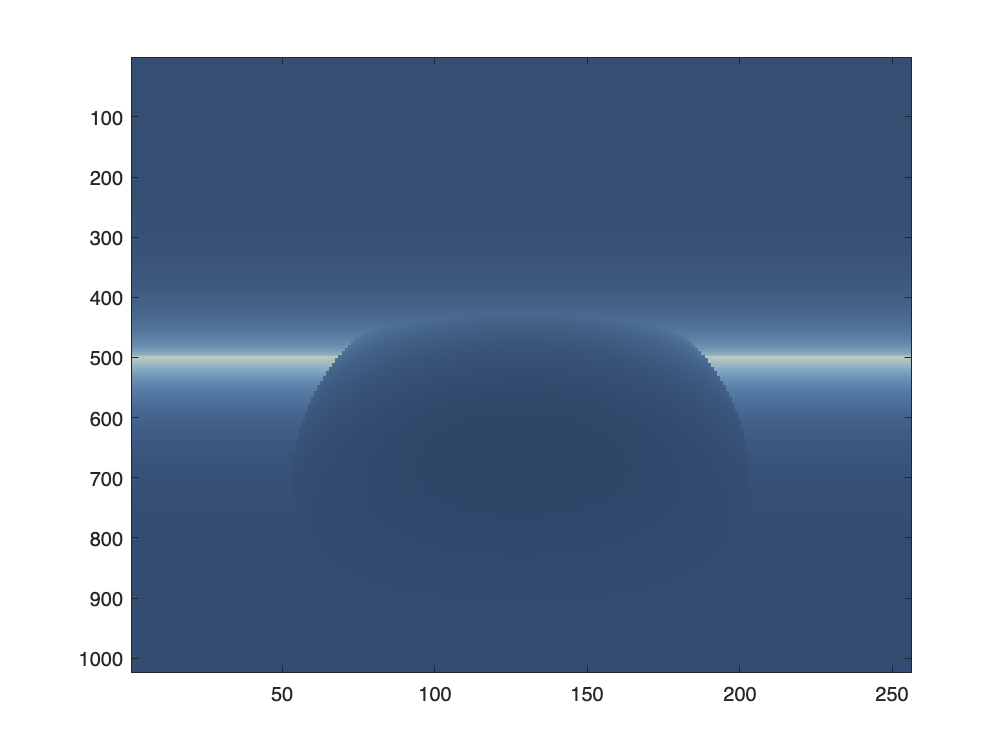

sunDir = [cosd(90),0,sind(90)];
viewPos = [0,0,1.001];
theta = linspace(-pi/2, pi/2, 256);
phi = linspace(-pi/2, pi/2, 1024);
[T, P]=meshgrid(theta, phi);
I = [];

viewDir = [];
viewDir(:,1) = cos(T(:)).*cos(P(:));
viewDir(:,2) = sin(T(:)).*cos(P(:));
viewDir(:,3) = sin(P(:));
viewPos = viewPos + 0.*T(:);

% Process indata
r = vecnorm(viewPos,2,2);
rmu = dot(viewPos,viewDir,2);

% Map to atmosphere
delta = rmu .^ 2 - r .^ 2 + atmosphere.Rt .^ 2;
distance_to_top_atmosphere_boundary = -rmu - ...
      sqrt(max(0, rmu .^ 2 - r .^ 2 + atmosphere.Rt .^ 2));
  % If the viewer is in space and the view ray intersects the atmosphere, move
  % the viewer to the top atmosphere boundary (along the view ray):
bInSpace = delta >= 0 & distance_to_top_atmosphere_boundary > 0.0;
distance_to_top_atmosphere_boundary = distance_to_top_atmosphere_boundary(bInSpace);
viewPos(bInSpace, :) = viewPos(bInSpace, :) + viewDir(bInSpace, :) .* distance_to_top_atmosphere_boundary;
r(bInSpace) = atmosphere.Rt;
rmu(bInSpace) = rmu(bInSpace) + distance_to_top_atmosphere_boundary;

mu = rmu ./ r;
mu_s = dot(viewPos, sunDir + 0*T(:),2)./vecnorm(viewPos,2,2);
nu = dot(viewDir, sunDir + 0*T(:),2);

% Compute scattering
%kSolarIrradiance = abs(randn(48,1));
I = GetScattering(r, mu, mu_s, nu, ...
    kSolarIrradiance, atmosphere, 1);

% Compute Transmittance
d = -rmu -...
sqrt(rmu .* rmu - r .* r + atmosphere.Rg .* atmosphere.Rg);
ray_r_mu_intersects_ground = RayIntersectsGround(r, mu, atmosphere.Rg);
tr2_ = GetTransmittance(atmosphere, atmosphere.cachedTransmittence,...
      r, mu, d, ray_r_mu_intersects_ground);
tr0_ = GetTransmittanceToTopAtmosphereBoundary(...
    atmosphere, atmosphere.cachedTransmittence,...
      r, mu);
tr0_(ray_r_mu_intersects_ground,:) = tr2_(ray_r_mu_intersects_ground,:);

% Add a sphere
kSphereCenter = [0.01,0.000,1.005];
kSphereRadius = 0.008;
p = viewPos - kSphereCenter;
p_dot_v = dot(p, viewDir, 2);
p_dot_p = dot(p, p, 2);
ray_sphere_center_squared_distance = p_dot_p - p_dot_v .* p_dot_v;

distance_to_intersection = -p_dot_v - sqrt(...
      kSphereRadius .^ 2 - ray_sphere_center_squared_distance);
distance_to_intersection(kSphereRadius.^2 < ray_sphere_center_squared_distance) = -1.0;
%if (distance_to_intersection > 0.0) {
    point = viewPos + viewDir .* distance_to_intersection;

    % Compute the radiance reflected by the sphere.
    [I2, tr1_, sp0_] = GetScatteringToPoint(r, mu, mu_s, nu, distance_to_intersection,...
        kSolarIrradiance, atmosphere, 1);
%}
I(distance_to_intersection>0,:) = I2(distance_to_intersection>0,:);
sp0_(distance_to_intersection<0,:) = -1;
tr0_(distance_to_intersection>0,:) = tr1_(distance_to_intersection>0,:);
for l = 1:3
    tr0(:,:,l) = reshape(tr0_(:,l), size(T,1),[]);
    sp0(:,:,l) = reshape(sp0_(:,l), size(T,1),[]);
end
% Irradiance to RGB
Cvp = I;

% Tonemapping
exposure = 10;
%kr = kWhite(1);kg = kWhite(2);kb = kWhite(3);
%white_point = [kr,kg,kb]./((kr+kg+kb)/3);
%Cvp = Cvp ./ white_point;
Cvp = (1.0 - exp(-exposure .* max(Cvp, 0))).^(1.0/2.2);

C = [];
% Process outdata
for l = 1:3
    C(:,:,l) = reshape(Cvp(:,l), size(T,1),[]);
end

clf,figure
image(C)


%[T1,R1] = pol2cart(T, cos(P));
%warp(T1,R1,0*T1,C),view(2),shading interp,view(2),axis equal,set(gca,'color','k')
%warp(T1,R1,0*T1,tonemapfarbman(max(C,0),'Exposure',1.0)),view(2),shading interp,view(2),axis equal,set(gca,'color','k')
%image(tonemapfarbman(max(C,0),'Exposure',1.0)),shading interp

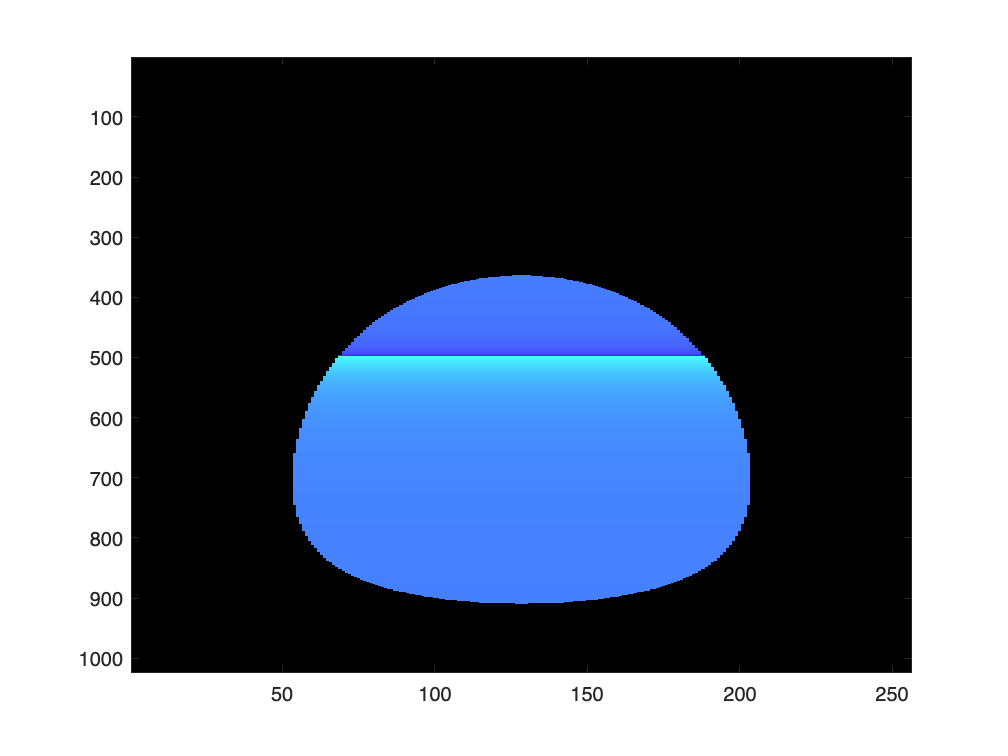

% Compare to 
[uvw0_, uvw1_] = GetUVWToPoint(r, mu, mu_s, nu, distance_to_intersection,...
        kSolarIrradiance, atmosphere, 1);
uvw0_(distance_to_intersection<0,:) = -1;
uvw1_(distance_to_intersection<0,:) = -1;
for l = 1:3
    u0(:,:,l) = reshape(uvw0_(:,l), size(T,1),[]);
    u1(:,:,l) = reshape(uvw1_(:,l), size(T,1),[]);
end
image(u0)

function [uvw0, uvw1] = GetUVWToPoint(r, mu, mu_s, nu, d, solarIrradiance, atmosphere, use_cache)

[u_r, u_mu, u_mus, u_nu] = RMuMusNuEncoding(atmosphere, r, mu, mu_s, nu);

ray_r_mu_intersects_ground = RayIntersectsGround(r, mu, atmosphere.Rg);

r_p = ClampRadius(sqrt(d .* d + 2.0 * r .* mu .* d + r .* r), atmosphere.Rg, atmosphere.Rt);
mu_p = (r .* mu + d) ./ r_p;
mu_s_p = (r .* mu_s + d .* nu) ./ r_p;

[u_r_p, u_mu_p, u_mus_p, ~] = RMuMusNuEncoding(atmosphere, r_p, mu_p, mu_s_p, nu);

uvw0 = [u_r, u_mu, u_mus];
uvw1 = [u_r_p, u_mu_p, u_mus_p];
end

function [out, transmittence, rayleighScatter_p] = GetScatteringToPoint(r, mu, mu_s, nu, d, solarIrradiance, atmosphere, use_cache)

[u_r, u_mu, u_mus, u_nu] = RMuMusNuEncoding(atmosphere, r, mu, mu_s, nu);
rayleighScatter = squeeze(atmosphere.cachedRayleigh(u_r, u_mu, u_mus, u_nu));
mieScatter = squeeze(atmosphere.cachedMie(u_r, u_mu, u_mus, u_nu));

ray_r_mu_intersects_ground = RayIntersectsGround(r, mu, atmosphere.Rg);
transmittence = ...
      GetTransmittance( ...
          atmosphere, atmosphere.cachedTransmittence, r, mu, d, ray_r_mu_intersects_ground);

r_p = ClampRadius(sqrt(d .* d + 2.0 * r .* mu .* d + r .* r), atmosphere.Rg, atmosphere.Rt);
mu_p = (r .* mu + d) ./ r_p;
mu_s_p = (r .* mu_s + d .* nu) ./ r_p;

[u_r_p, u_mu_p, u_mus_p, ~] = RMuMusNuEncoding(atmosphere, r_p, mu_p, mu_s_p, nu);
rayleighScatter_p = squeeze(atmosphere.cachedRayleigh(u_r_p, u_mu_p, u_mus_p, u_nu));
mieScatter_p = squeeze(atmosphere.cachedMie(u_r_p, u_mu_p, u_mus_p, u_nu));

rayleighScatter = rayleighScatter - transmittence.*rayleighScatter_p;
mieScatter = mieScatter - transmittence.*mieScatter_p;

for l = 1:numel(solarIrradiance)
    out(:,l) = solarIrradiance(l) .* RayleighPhaseFunction(nu) .* rayleighScatter(:,l) ...
             + solarIrradiance(l) .* MiePhaseFunction(atmosphere.mie_phase_function_g, nu) .* mieScatter(:,l);
end
end

function out = GetScattering(r, mu, mu_s, nu, solarIrradiance, atmosphere, use_cache)
if use_cache
    [u_r, u_mu, u_mus, u_nu] = RMuMusNuEncoding(atmosphere, r, mu, mu_s, nu);
    rayleighScatter = squeeze(atmosphere.cachedRayleigh(u_r, u_mu, u_mus, u_nu));
    mieScatter = squeeze(atmosphere.cachedMie(u_r, u_mu, u_mus, u_nu));
else
    [rayleighScatter, mieScatter] = F_Transmittence(...
    atmosphere, ...
    r(:), mu(:), mu_s(:), nu(:));
end

for l = 1:numel(solarIrradiance)
    out(:,l) = solarIrradiance(l) .* RayleighPhaseFunction(nu) .* rayleighScatter(:,l) ...
             + solarIrradiance(l) .* MiePhaseFunction(atmosphere.mie_phase_function_g, nu) .* mieScatter(:,l);
end
end

function C = RadianceToRGB(I, lambda)
c_bar = Lambda2RGB(lambda*1e3);
C = 0*I(:,1:3);
dlambda = [0, diff(lambda.'*1e3)];
for l = 1:numel(lambda)
    C(:,1) = C(:,1) + I(:,l).*c_bar(l,1)*dlambda(l);
    C(:,2) = C(:,2) + I(:,l).*c_bar(l,2)*dlambda(l);
    C(:,3) = C(:,3) + I(:,l).*c_bar(l,3)*dlambda(l);
end
end